clear
clc
close all

KAC_Kg_kv = -1.4812

G_deltabar_nye =
 
   -0.3407 s^2 - 0.511 s + 748.7
  -------------------------------
  s^3 + 34.41 s^2 + 201 s + 748.7
 
连续时间传递函数。
模型属性


KAC_Kg_kv = -2.2809

G_deltabar_nye =
 
   -0.5246 s^2 - 0.7869 s + 1153
  --------------------------------
  s^3 + 38.76 s^2 + 265.3 s + 1153
 
连续时间传递函数。
模型属性


KAC_Kg_kv = -2.7711

G_deltabar_nye =
 
   -0.6373 s^2 - 0.956 s + 1401
  ------------------------------
  s^3 + 43.36 s^2 + 308 s + 1401
 
连续时间传递函数。
模型属性


KAC_Kg_kv = -2.7021

G_deltabar_nye =
 
   -0.6215 s^2 - 0.9322 s + 1366
  --------------------------------
  s^3 + 48.08 s^2 + 317.7 s + 1366
 
连续时间传递函数。
模型属性


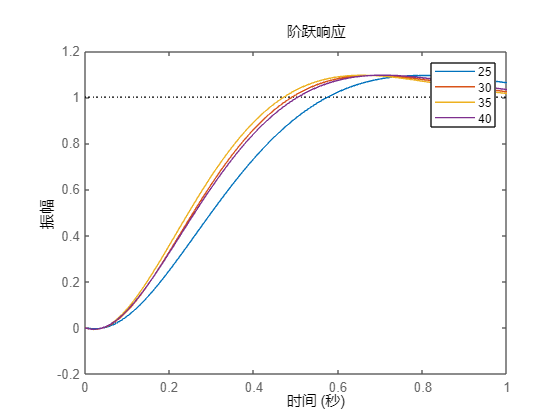

% 弹体气动数据
V = 914.4;
a1 = 1.5;
a2 = -250;
a3 = 280;
a4 = 1.6;
a5 = 0.23;

kv = V/(57.3*9.8);

A1 = a1+a4;
A2 = a2+a1*a4;

omega_n = 5.15;
omega_n1 = 28.23;
epsilon = 0.6;

N2 = omega_n1+2*epsilon*omega_n-A1;
N1 = omega_n^2+2*epsilon*omega_n*omega_n1-A2;
N0 = omega_n^2*omega_n1;

omega_a = a4-a2*a5/a3;
Kg = (omega_n1+2*epsilon*omega_n-A1+a5*omega_n1*omega_n^2/(a3*a4-a2*a5))/(-a3);
K_AC = omega_n1*omega_n^2/(Kg*kv);
KAC_Kg_kv =  -(omega_n^2*omega_n1)/(a3*a4-a2*a5)

G_deltabar_nye = tf(KAC_Kg_kv.*[a5 a1*a5 -(a3*a4-a2*a5)], [1 A1+N2 A2+N1 N0])
step(G_deltabar_nye,1)

omega_n = 6.05;
omega_n1 = 31.5;
epsilon = 0.6;

N2 = omega_n1+2*epsilon*omega_n-A1;
N1 = omega_n^2+2*epsilon*omega_n*omega_n1-A2;
N0 = omega_n^2*omega_n1;

omega_a = a4-a2*a5/a3;
KA_omegai_KR = (omega_n1*omega_n^2/omega_a-(omega_n^2+2*epsilon*omega_n*omega_n1-A2-(omega_n1+2*epsilon*omega_n-A1)*omega_a))/((-a3+a5*(omega_a-a1))*kv);
KAC_Kg_kv =  -(omega_n^2*omega_n1)/(a3*a4-a2*a5)

G_deltabar_nye = tf(KAC_Kg_kv.*[a5 a1*a5 -(a3*a4-a2*a5)], [1 A1+N2 A2+N1 N0])

hold on
step(G_deltabar_nye,1)

omega_n = 6.25;
omega_n1 = 35.86;
epsilon = 0.6;

N2 = omega_n1+2*epsilon*omega_n-A1;
N1 = omega_n^2+2*epsilon*omega_n*omega_n1-A2;
N0 = omega_n^2*omega_n1;

omega_a = a4-a2*a5/a3;
KA_omegai_KR = (omega_n1*omega_n^2/omega_a-(omega_n^2+2*epsilon*omega_n*omega_n1-A2-(omega_n1+2*epsilon*omega_n-A1)*omega_a))/((-a3+a5*(omega_a-a1))*kv);
KAC_Kg_kv =  -(omega_n^2*omega_n1)/(a3*a4-a2*a5)

G_deltabar_nye = tf(KAC_Kg_kv.*[a5 a1*a5 -(a3*a4-a2*a5)], [1 A1+N2 A2+N1 N0])

hold on
step(G_deltabar_nye,1)

omega_n = 5.76;
omega_n1 = 41.17;
epsilon = 0.6;

N2 = omega_n1+2*epsilon*omega_n-A1;
N1 = omega_n^2+2*epsilon*omega_n*omega_n1-A2;
N0 = omega_n^2*omega_n1;

omega_a = a4-a2*a5/a3;
KA_omegai_KR = (omega_n1*omega_n^2/omega_a-(omega_n^2+2*epsilon*omega_n*omega_n1-A2-(omega_n1+2*epsilon*omega_n-A1)*omega_a))/((-a3+a5*(omega_a-a1))*kv);

KAC_Kg_kv =  -(omega_n^2*omega_n1)/(a3*a4-a2*a5)
G_deltabar_nye = tf(KAC_Kg_kv.*[a5 a1*a5 -(a3*a4-a2*a5)], [1 A1+N2 A2+N1 N0])

hold on
step(G_deltabar_nye,1)
legend('25','30','35','40')